# Computational burden calculation

Imperix: 2600 flops = 15% CPU burden

cpu_flops_ratio = 15/2600;
cpu_flops_ratio = 10/2600;

## Neural Network

nx = 14;     % Inputs
nl = 3;      % Hidden layers
nh = 5 * nx; % Neurons per hidden layer
ny = 3;      % Outputs
NN_mults = nh * (nx + 1) + (nl - 1) * nh * (nh + 1) + ny * (nh + 1); %+ nl * nh
NN_sums  = nh * nx + (nl - 1) * nh * nh + ny * nh; %+ nl * nh
NN_relu_operations = nh * nl;
NN_tanh_operations = ny;
NN_flops = NN_mults + NN_sums + NN_relu_operations + NN_tanh_operations;
NN_CPU_burden = NN_flops * cpu_flops_ratio;

## LONG HORIZON Block Coordinate Descent

Nl = 50; % BCD Iterations
Np = 10; % Horizon length
n = 2;   % Circulating currents

BCD_cholesky = Nl * (Np^3 + (n * Np)^3) / 6;
BCD_triang_solutions = Nl * (Np^2 + (n * Np)^2) / 2;
BCD_H_inv_flops = BCD_cholesky + 2 * BCD_triang_solutions;

BCD_mv_multiplication_mults = Nl * Np * (Np + n * n * Np);
BCD_mv_multiplication_sums = Nl * Np * ((Np - 1) + n * (n * Np - 1));
BCD_mv_flops = BCD_mv_multiplication_mults + BCD_mv_multiplication_sums;

BCD_flops = BCD_H_inv_flops + BCD_mv_flops;
BCD_CPU_burden = BCD_flops * cpu_flops_ratio;

## Computational gain

NN_flops

NN_flops = 22406

NN_CPU_burden

NN_CPU_burden = 86.1769

BCD_flops

BCD_flops = 148500

BCD_CPU_burden

BCD_CPU_burden = 571.1538

BCD_flops / NN_flops

ans = 6.6277

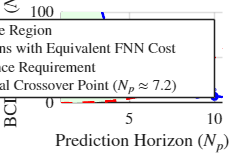

clc; clear; close all;

%% 1. Neural Network FLOPs Calculation (Fixed Cost)
nx = 14; nl = 3; nh = 5 * nx; ny = 3;

NN_mults = nh * (nx + 1) + (nl - 1) * nh * (nh + 1) + ny * (nh + 1);
NN_sums  = nh * nx + (nl - 1) * nh * nh + ny * nh;
NN_relu_operations = nh * nl;
NN_tanh_operations = ny;

NN_flops = NN_mults + NN_sums + NN_relu_operations + NN_tanh_operations;

%% 2. BCD Computational Cost Curve (Blue Hyperbola)
n = 2; % Circulating currents
Np_range = 1:0.01:10.5; 

% Vectorized cost of 1 BCD iteration
BCD_chol_1it   = (Np_range.^3 + (n * Np_range).^3) / 6;
BCD_triang_1it = (Np_range.^2 + (n * Np_range).^2) / 2;
BCD_H_inv_1it  = BCD_chol_1it + 2 * BCD_triang_1it;
BCD_mv_mult_1it = Np_range .* (Np_range + n * n * Np_range);
BCD_mv_sum_1it  = Np_range .* ((Np_range - 1) + n * (n * Np_range - 1));
BCD_mv_1it      = BCD_mv_mult_1it + BCD_mv_sum_1it;

BCD_cost_per_iter = BCD_H_inv_1it + BCD_mv_1it;

% Max iterations allowed given the NN budget
Nl_budget_curve = NN_flops ./ BCD_cost_per_iter;

%% 3. Tolerance Requirement Curve (Red Dashed Line)
Np_obs = [10, 20];
Nl_obs = [50, 500];

% Log-Log fit
coeffs = polyfit(log(Np_obs), log(Nl_obs), 1);
b_exp = coeffs(1);        
a_coeff = exp(coeffs(2)); 

% Required iterations curve
Nl_required_curve = a_coeff * Np_range .^ b_exp;

%% 4. Plotting
% --- PARAMETROS DE FUENTE (MODIFICAR AQUI) ---
fs_axis_nums = 12;  % Tamaño de los números en los ejes (1, 2, 3...)
fs_labels    = 14;  % Tamaño de las etiquetas (Np, Nl)
fs_legend    = 11;  % Tamaño de la letra en la leyenda

figure('Color', 'w', 'Position', [100 100 900 600]);
hold on; grid on;

% --- A. Feasible Region (Fill) ---
idx_cross = find(Nl_required_curve > Nl_budget_curve, 1);
if isempty(idx_cross)
    idx_cross = length(Np_range);
end
Np_cross = Np_range(idx_cross);

x_fill = Np_range(1:idx_cross);
y_top = Nl_budget_curve(1:idx_cross);
y_bot = Nl_required_curve(1:idx_cross);
fill([x_fill, fliplr(x_fill)], [y_top, fliplr(y_bot)], ...
     [0.9, 1, 0.9], 'EdgeColor', 'none', 'DisplayName', 'BCD Feasible Region');

% --- B. Main Curves ---
% Agregamos \quad para engañar a la caja de la leyenda y hacerla más ancha
plot(Np_range, Nl_budget_curve, 'b-', 'LineWidth', 2, ...
    'DisplayName', 'BCD Iterations with Equivalent FNN Cost \quad');

plot(Np_range, Nl_required_curve, 'r--', 'LineWidth', 2, ...
    'DisplayName', 'BCD Tolerance Requirement');

% --- C. Markers on the Hyperbola ---
for k = 1:10
    val_y = interp1(Np_range, Nl_budget_curve, k);
    plot(k, val_y, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 6, 'HandleVisibility', 'off');
    
    offset = 4;
    if k < 3, offset = 6; end 
    text(k, val_y + offset, sprintf('%.0f', val_y), ...
        'Color', 'b', 'FontWeight', 'bold', 'HorizontalAlignment', 'center', ...
        'FontSize', 9, 'Interpreter', 'latex'); % Los números azules pequeños también en LaTeX
end

% --- D. Intersection Point (Star) ---
plot(Np_cross, Nl_budget_curve(idx_cross), 'p', 'MarkerSize', 14, ...
    'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Computational Crossover Point ($N_p \\approx %.1f$) \\quad \\quad', Np_cross));

% --- E. Formatting ---
% Aplicamos el tamaño de fuente definido arriba
xlabel('Prediction Horizon ($N_p$)', 'Interpreter', 'latex', 'FontSize', fs_labels);
ylabel('BCD Iterations ($N_l$)', 'Interpreter', 'latex', 'FontSize', fs_labels);

% ESTA ES LA LINEA MAGICA PARA QUE LOS NUMEROS DE LOS EJES SEAN LATEX
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', fs_axis_nums);

% Leyenda con tamaño controlado
legend('Location', 'northeast', 'Interpreter', 'latex', 'FontSize', fs_legend);

% Axes limits
xlim([1 10.5]); 
ylim([0 100]);


%% 5. Saving the Figure (SOLUCIÓN FINAL - Método Print)
width_cm = 16;
height_cm = 10;

set(gcf, 'Units', 'centimeters');
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1), pos(2), width_cm, height_cm]);

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPositionMode', 'manual'); 
set(gcf, 'PaperSize', [width_cm, height_cm]); 
set(gcf, 'PaperPosition', [0, 0, width_cm, height_cm]);

drawnow;

filename = 'BCD_vs_NN_Complexity.pdf';
print(gcf, filename, '-dpdf', '-painters'); 


fprintf('Figura guardada exitosamente: %s (%dx%d cm)\n', filename, width_cm, height_cm);

Figura guardada exitosamente: BCD_vs_NN_Complexity.pdf (16x10 cm)
